Decentralized Numerical Testing of W>0

clear all
close all
clc

N = 5;
W = rand(5,5)

W =     0.0292    0.1304    0.9543    0.7956    0.2364
    0.3904    0.9844    0.1974    0.7682    0.3105
    0.4373    0.0657    0.0833    0.8720    0.7156
    0.5206    0.5793    0.8839    0.9161    0.0827
    0.4929    0.5808    0.0157    0.2738    0.6755


W = W+W'

W =     0.0583    0.5208    1.3916    1.3162    0.7293
    0.5208    1.9688    0.2631    1.3475    0.8913
    1.3916    0.2631    0.1667    1.7559    0.7313
    1.3162    1.3475    1.7559    1.8322    0.3565
    0.7293    0.8913    0.7313    0.3565    1.3510



for i = 1:1:N
    i
    
    if i==1
        W_i = []
        W_ii = W(i,i)
    
        tildeW_i{i} = []
        tildeW_ii{i} = W_ii
        
    else
        W_i = W(i,1:i-1)
        W_ii = W(i,i)
        
        for j=1:1:i-1
            j
            tildeW_jVal = tildeW_i{j}
            tildeW_jjVal = tildeW_ii{j}
            if j==1
                A_i = tildeW_jjVal
                D_i = 1/tildeW_jjVal
                Z = 0
            else 
                A_i = [A_i,Z';tildeW_jVal,tildeW_jjVal]
                D_i = [D_i,Z';Z,1/tildeW_jjVal]
                Z = [Z,0]
            end         
           
            
        end
        B_i = A_i*D_i*A_i'
        tildeW_iiVal = W_ii - W_i*inv(B_i)*W_i'
        tildeW_iVal = W_i/(D_i*A_i')
        testMat = [B_i, W_i'; W_i, W_ii]
        
        tildeW_i{i} = tildeW_iVal
        tildeW_ii{i} = tildeW_iiVal
        
        
    end
    
end

i = 1


W_i =

     []



W_ii = 0.0583

tildeW_i = 1×1 cell array
    {0×0 double}


tildeW_ii = 1×1 cell array
    {[0.0583]}


i = 2

W_i = 0.5208

W_ii = 1.9688

j = 1


tildeW_jVal =

     []



tildeW_jjVal = 0.0583

A_i = 0.0583

D_i = 17.1485

Z = 0

B_i = 0.0583

tildeW_iiVal = -2.6825

tildeW_iVal = 0.5208

testMat =     0.0583    0.5208
    0.5208    1.9688


tildeW_i = 1×2 cell array
    {0×0 double}    {[0.5208]}


tildeW_ii = 1×2 cell array
    {[0.0583]}    {[-2.6825]}


i = 3

W_i =     1.3916    0.2631


W_ii = 0.1667

j = 1


tildeW_jVal =

     []



tildeW_jjVal = 0.0583

A_i = 0.0583

D_i = 17.1485

Z = 0

j = 2

tildeW_jVal = 0.5208

tildeW_jjVal = -2.6825

A_i =     0.0583         0
    0.5208   -2.6825


D_i =    17.1485         0
         0   -0.3728


Z =      0     0


B_i =     0.0583    0.5208
    0.5208    1.9688


tildeW_iiVal = 22.1265

tildeW_iVal =     1.3916  -12.1652


testMat =     0.0583    0.5208    1.3916
    0.5208    1.9688    0.2631
    1.3916    0.2631    0.1667


tildeW_i = 1×3 cell array
    {0×0 double}    {[0.5208]}    {[1.3916 -12.1652]}


tildeW_ii = 1×3 cell array
    {[0.0583]}    {[-2.6825]}    {[22.1265]}


i = 4

W_i =     1.3162    1.3475    1.7559


W_ii = 1.8322

j = 1


tildeW_jVal =

     []



tildeW_jjVal = 0.0583

A_i = 0.0583

D_i = 17.1485

Z = 0

j = 2

tildeW_jVal = 0.5208

tildeW_jjVal = -2.6825

A_i =     0.0583         0
    0.5208   -2.6825


D_i =    17.1485         0
         0   -0.3728


Z =      0     0


j = 3

tildeW_jVal =     1.3916  -12.1652


tildeW_jjVal = 22.1265

A_i =     0.0583         0         0
    0.5208   -2.6825         0
    1.3916  -12.1652   22.1265


D_i =    17.1485         0         0
         0   -0.3728         0
         0         0    0.0452


Z =      0     0     0


B_i =     0.0583    0.5208    1.3916
    0.5208    1.9688    0.2631
    1.3916    0.2631    0.1667


tildeW_iiVal = -1.4079

tildeW_iVal =     1.3162  -10.4078   17.5445


testMat =     0.0583    0.5208    1.3916    1.3162
    0.5208    1.9688    0.2631    1.3475
    1.3916    0.2631    0.1667    1.7559
    1.3162    1.3475    1.7559    1.8322


tildeW_i = 1×4 cell array
    {0×0 double}    {[0.5208]}    {[1.3916 -12.1652]}    {[1.3162 -10.4078 17.5445]}


tildeW_ii = 1×4 cell array
    {[0.0583]}    {[-2.6825]}    {[22.1265]}    {[-1.4079]}


i = 5

W_i =     0.7293    0.8913    0.7313    0.3565


W_ii = 1.3510

j = 1


tildeW_jVal =

     []



tildeW_jjVal = 0.0583

A_i = 0.0583

D_i = 17.1485

Z = 0

j = 2

tildeW_jVal = 0.5208

tildeW_jjVal = -2.6825

A_i =     0.0583         0
    0.5208   -2.6825


D_i =    17.1485         0
         0   -0.3728


Z =      0     0


j = 3

tildeW_jVal =     1.3916  -12.1652


tildeW_jjVal = 22.1265

A_i =     0.0583         0         0
    0.5208   -2.6825         0
    1.3916  -12.1652   22.1265


D_i =    17.1485         0         0
         0   -0.3728         0
         0         0    0.0452


Z =      0     0     0


j = 4

tildeW_jVal =     1.3162  -10.4078   17.5445


tildeW_jjVal = -1.4079

A_i =     0.0583         0         0         0
    0.5208   -2.6825         0         0
    1.3916  -12.1652   22.1265         0
    1.3162  -10.4078   17.5445   -1.4079


D_i =    17.1485         0         0         0
         0   -0.3728         0         0
         0         0    0.0452         0
         0         0         0   -0.7103


Z =      0     0     0     0


B_i =     0.0583    0.5208    1.3916    1.3162
    0.5208    1.9688    0.2631    1.3475
    1.3916    0.2631    0.1667    1.7559
    1.3162    1.3475    1.7559    1.8322


tildeW_iiVal = 1.6731

tildeW_iVal =     0.7293   -5.6217    8.8226   -1.2882


testMat =     0.0583    0.5208    1.3916    1.3162    0.7293
    0.5208    1.9688    0.2631    1.3475    0.8913
    1.3916    0.2631    0.1667    1.7559    0.7313
    1.3162    1.3475    1.7559    1.8322    0.3565
    0.7293    0.8913    0.7313    0.3565    1.3510


tildeW_i = 1×5 cell array
    {0×0 double}    {[0.5208]}    {[1.3916 -12.1652]}    {[1.3162 -10.4078 17.5445]}    {[0.7293 -5.6217 8.8226 -1.2882]}


tildeW_ii = 1×5 cell array
    {[0.0583]}    {[-2.6825]}    {[22.1265]}    {[-1.4079]}    {[1.6731]}


Communication Cost Optimization

clear all
close all 
clc

rng(5) % 5 seems to be the ideal case

%% Create a network object
network = Network(0);

% Number of subsystems
numOfSubsystems = 7; 
dimentionOfSpace = 2;
sizeOfSpace = 1;
communicationRadius = 0.6;

% subsystem dims
for i = 1:1:numOfSubsystems
    dims{i}.n = 2; % x
    dims{i}.p = 1; % u
    dims{i}.q = 1; % w  
    dims{i}.m = 1; % y
    dims{i}.l = 1; % y
end

% Create the network and plot it
network = network.loadARandomNetwork(numOfSubsystems,dimentionOfSpace,sizeOfSpace,communicationRadius,dims);
network.shiftLocations();
network.drawNetwork(1,false);

[bestIndexing, minCost, worstIndexing, maxCost, basicIndexingCost] = network.findOptimumIndexing()

bestIndexing =      3     7     6     2     4     1     5


minCost = 64

worstIndexing =      6     5     3     4     7     2     1


maxCost = 220

basicIndexingCost = 156

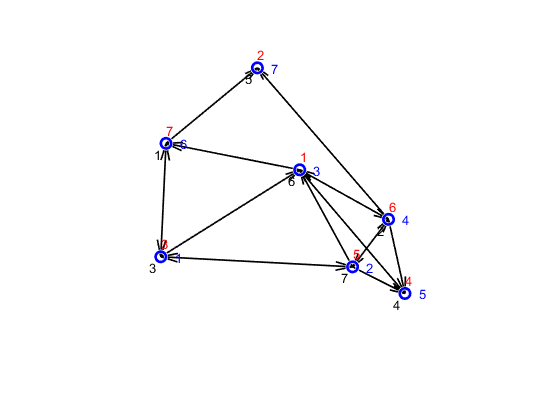

network.drawIndexing(bestIndexing,0,'b')
network.drawIndexing(worstIndexing,pi/2,'r')

YALMIP Based LMI Solutions : Stability

clear all
close all 
clc

% addpath('C:\Program Files\Mosek\9.3\toolbox\R2015a')
% solverOptions = sdpsettings('solver','mosek','verbose',0);
solverOptions = sdpsettings('solver','mosek');
n = 2; % 2
seedVal = 17; % 17(all stable/dissipative)
rng(seedVal);

sysSS = rss(n,1);
A = sysSS.A

A =    -1.3296    0.0075
    0.0075   -1.3108


B = sysSS.B

B =     0.3709
    0.7810


C = sysSS.C

C =    -1.3599    0.3476


D = sysSS.D

D = 0




% % % % Stability Analysis
% % % % P = sdpvar(n,n)
P = diag(sdpvar(n,1)); % Stability analysis with diagonal matrix
con1 = P >= 0;
con2 = A'*P + P*A <= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 2               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible1 = sol.problem==0

isFeasible1 = logical
   1


PVal = value(P);
eigs = eig(A)

eigs =    -1.3322
   -1.3081




% % % % Stabilization with FSF control
M = diag(sdpvar(n,1));
L = sdpvar(1,n);
con1 = M >= 0;
con2 = M*A' + A*M + L'*B' + B*L <= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 4               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible2 = sol.problem==0

isFeasible2 = logical
   1


MVal = value(M);
LVal = value(L);
K = LVal/MVal

K =    -0.0706    0.8272


eigs = eig(A+B*K)

eigs =    -1.3334
   -0.6871


KStab = K;


% % % % Stable observer design
P = diag(sdpvar(n,1));
K = sdpvar(n,1);
con1 = P >= 0;
con2 = A'*P + P*A - C'*K' - K*C <= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 4               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible3 = sol.problem==0

isFeasible3 = logical
   1


PVal = value(P);
KVal = value(K);
L = PVal\KVal

L =     0.5787
    0.0799


eigs = eig(A-L*C)

eigs =    -0.5719
   -1.3092


LStab = L;


% Stabilization using DOF control
Y = diag(sdpvar(n,1));
X = diag(sdpvar(n,1));
An = sdpvar(n,n,'full');
Bn = sdpvar(n,1);
Cn = sdpvar(1,n);
Dn = sdpvar(1,1);
I = eye(n);
con1 = X >= 0;
con2 = Y >= 0;
con3 = [Y, I; I, X] >= 0;
c1 = A*Y+B*Cn;
c2 = A+B*Dn*C+An';
c3 = X*A+Bn*C;
con4 = [-c1-c1', -c2; -c2', -c3-c3']>=0;
sol = optimize([con1,con2,con3,con4],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 13              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 4               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

isFeasible4 = sol.problem==0

isFeasible4 = logical
   1


XVal = value(X);
YVal = value(Y);
AnVal = value(An);
BnVal = value(Bn);
CnVal = value(Cn);
DnVal = value(Dn);
[M,N] = lu(I-XVal*YVal); % controller parameters
N = N';
Ac = M\(AnVal-BnVal*C*YVal-XVal*B*CnVal-XVal*(A-B*DnVal*C)*YVal)/(N') 

Ac =    -1.5315    0.7747
   -1.1562   -0.5714


Bc = M\(BnVal-XVal*B*DnVal)

Bc =    -0.0884
    2.6338


Cc = (CnVal-DnVal*C*YVal)/(N')

Cc =     0.6334   -0.6685


Dc = DnVal

Dc = -1.4673

Abar = [A+B*Dc*C, B*Cc; Bc*C, Ac]; %closed loop system
% Bbar = [E+B*Dc*F;Bc*F]
% Cbar = [G+H*Dc*C, H*Cc]
% Dbar = [J+H*Dc*F]
eigs = eig(Abar)

eigs =   -0.9328 + 0.5171i
  -0.9328 - 0.5171i
  -1.2145 + 0.0000i
  -1.3213 + 0.0000i


AcStab = Ac; BcStab = Bc; CcStab = Cc; DcStab = Dc; 

YALMIP Based LMI Solutions : Dissipativity

% clear all
% close all 
% clc
% n = 2
% sdpsettings('solver','mosek','verbose',0);

% rng(seedVal) % 7 good for FSF, but OBS and DOF are marginally feasible

% sysSS = rss(n,1);
% A = sysSS.A
% B = sysSS.B
% C = sysSS.C
% D = sysSS.D
E = 0.01*ones(n,1) % Noice input to state dynamics

E =     0.0100
    0.0100


F = 0.01*ones(1,1) % Noice input to output dynamics

F = 0.0100


G = ones(1,n) % Perf metric

G =      1     1


H = ones(1,1)

H = 1

J = 0.01*ones(1,1)

J = 0.0100


nu = 0.001  % input feedforward passivity % 0

nu = 1.0000e-03

rho = 1 % output feedback passivity

rho = 1

Q = -rho*eye(1,1) % QSR passivity indices interested

Q = -1

S =  0.5*eye(1,1)

S = 0.5000

R = -nu*eye(1,1) 

R = -1.0000e-03



% % % % Dissipativity Analysis (w to y)
% % % % P = sdpvar(n,n)
P = diag(sdpvar(n,1)); % Stability analysis with diagonal matrix
con1 = P >= 0;
c1 = -A'*P-P*A;
c2 = -P*E+C'*S;
c3 = F'*S+S'*F+R;
con2 = [c1, c2, C'; c2', c3, F'; C, F, -inv(Q)] >= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 2               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible5 = sol.problem==0

isFeasible5 = logical
   0


PVal = value(P);
eigs = eig(A)

eigs =    -1.3322
   -1.3081




% % % % Dissipativation with FSF control
M = diag(sdpvar(n,1));
L = sdpvar(1,n);
con1 = M >= 0;
c1 = A*M +B*L;
c2 = -E+M*C'*S;
c3 = F'*S+S'*F+R;
con2 = [-c1-c1', c2, M*C'; c2', c3, F'; C*M', F, -inv(Q)] >= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 4               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible6 = sol.problem==0

isFeasible6 = logical
   1


MVal = value(M);
LVal = value(L);
K = LVal/MVal

K =    -7.3232    0.3165


eigs = eig(A+B*K)

eigs =    -3.7835
   -1.3259


KDiss = K;


% % % % Dissipative observer design
P = diag(sdpvar(n,1));
K = sdpvar(n,1);
con1 = P >= 0;
c1 = P*A-K*C;
c2 = -P*E+K*F+G'*S;
c3 = J'*S+S'*J+R;
con2 = [-c1-c1', c2, G'; c2', c3, J'; G, J, -inv(Q)] >= 0;
sol = optimize([con1,con2],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 4               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number          

isFeasible7 = sol.problem==0

isFeasible7 = logical
   1


PVal = value(P);
KVal = value(K);
L = PVal\KVal

L =    -0.8025
   -1.0963


eigs = eig(A-L*C)

eigs =    -2.0373
   -1.3134


LDiss = L;


% % % % Dissipativation using DOF control
% % % % Y = sdpvar(n,n)
% % % % X = sdpvar(n,n)
Y = diag(sdpvar(n,1));
X = diag(sdpvar(n,1));
An = sdpvar(n,n,'full');
Bn = sdpvar(n,1);
Cn = sdpvar(1,n);
Dn = sdpvar(1,1);
I = eye(n);
con1 = X >= 0;
con2 = Y >= 0;
con3 = [Y, I; I, X] >= 0;
c1 = -A*Y-B*Cn;
c2 = -A-B*Dn*C-An';
c3 = -E-B*Dn*F+(Y*G'+Cn'*H')*S;
c4 = Y*G'+Cn'*H';
c5 = -X*A-Bn*C;
c6 = -X*E-Bn*F+(G'+C'*Dn'*H')*S;
c7 = G'+C'*Dn'*H';
c8 = (J'+F'*Dn'*H')*S+S'*(J+H*Dn*F)+R;
c9 = J'+F'*Dn'*H';
con4 = [c1+c1', c2, c3, c4; c2', c5+c5', c6, c7; c3', c6', c8, c9; c4', c7', c9', -inv(Q)]>=0;
sol = optimize([con1,con2,con3,con4],[],solverOptions);

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 13              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 4               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

isFeasible8 = sol.problem==0

isFeasible8 = logical
   1


XVal = value(X);
YVal = value(Y);
AnVal = value(An);
BnVal = value(Bn);
CnVal = value(Cn);
DnVal = value(Dn);
[M,N] = lu(I-XVal*YVal); % controller parameters
N = N';
Ac = M\(AnVal-BnVal*C*YVal-XVal*B*CnVal-XVal*(A-B*DnVal*C)*YVal)/(N') 

Ac =    -0.8943   -0.4529
   -0.7544   -2.2988


Bc = M\(BnVal-XVal*B*DnVal)

Bc =    -4.0084
   -1.8483


Cc = (CnVal-DnVal*C*YVal)/(N')

Cc =     0.0389    0.1454


Dc = DnVal

Dc = 0.5770

Abar = [A+B*Dc*C, B*Cc; Bc*C, Ac]; %closed loop system
Bbar = [E+B*Dc*F;Bc*F];
Cbar = [G+H*Dc*C, H*Cc];
Dbar = [J+H*Dc*F];
eigs = eig(Abar)

eigs =    -2.6128
   -0.7137
   -1.3326
   -1.3088


AcDiss = Ac; BcDiss = Bc; CcDiss = Cc; DcDiss = Dc; 